Q = [2 2; 2 6]

Q =      2     2
     2     6



C = [2; 10]

C =      2
    10



pinv(Q)*Q

ans =     1.0000    0.0000
    0.0000    1.0000



x_min = -pinv(Q) * C

x_min =     1.0000
   -2.0000



rank(Q)

ans = 2

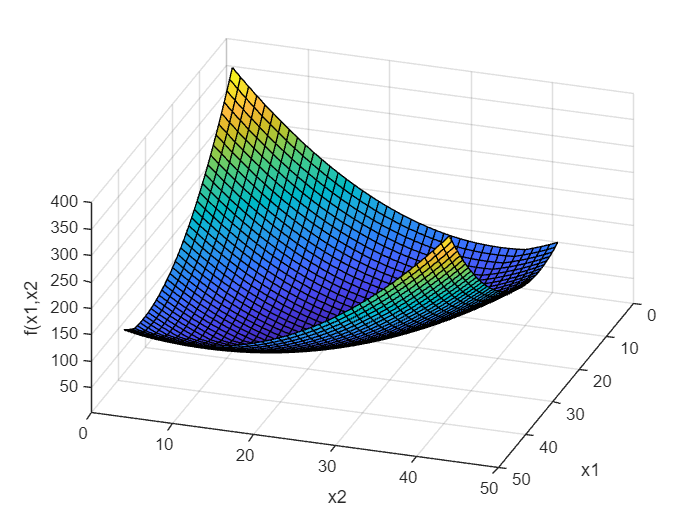



%Starting here, you can define a function f(x1,x2) and plot it. If you want
%a heatmap, change the "surf(f)" command to "map(f)"

x1 = -10:.5:10;
x2 = -10:.5:10;

clear min1
for i = 1:size(x1,2)
    for ii = 1:size(x2,2)
    f(i,ii) = x1(i)^2 + x1(i)*x2(ii) +x2(ii)^2 + 3*abs(x1(i) + x2(ii) + 2);
        if exist("min","var") ~= 1
            min1 = [i, ii, f(i,ii)];
        end
        if f(i,ii) < min(3)
            min1 = [i, ii, f(i,ii)];
        end
    end
end
hold on
surf(f)
view([119 38])
xlabel("x1")
ylabel("x2")
zlabel("f(x1,x2")
grid("on")

plot3(min1(1), min1(2), min1(3));

hold off

HW2 Problem3, Jet Thrust

syms rho S C_D0 K W T V
res = 1;   

T = 0.5*rho*S*V^2*C_D0 + (K*W^2)/ (0.5*rho*S*V^2)

$$T = \frac{C_{\mathrm{D0}}\,S\,V^{2}\,\rho }{2}+\frac{2\,K\,W^{2}}{S\,V^{2}\,\rho }$$

T0 = subs(T,[W S C_D0 K rho], [73000 950 0.015 0.05 1.7553e-3])

$$T0 = \frac{24575674792199550140416000}{76901478447383143\,V^{2}}+\frac{230704435342149429\,V^{2}}{18446744073709551616}$$


V0 = 100:res:900;
T0_V0 = double(subs(T0, V, V0))

T0_V0 = 1.0e+04 *

    3.2082    3.1455    3.0847    3.0256    2.9682    2.9124    2.8582    2.8056    2.7544    2.7046    2.6562    2.6091    2.5633    2.5187    2.4753    2.4330    2.3918    2.3516    2.3125    2.2744    2.2373    2.2010    2.1657    2.1312    2.0976    2.0648    2.0328    2.0015    1.9710    1.9412    1.9121    1.8837    1.8559    1.8287    1.8022    1.7763    1.7509    1.7261    1.7019    1.6782    1.6550    1.6323    1.6101    1.5884    1.5671    1.5463    1.5259    1.5059    1.4864    1.4672


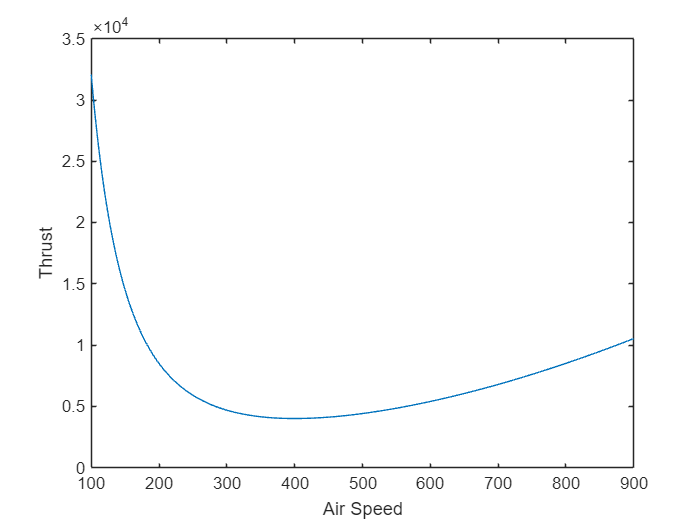

plot(V0,T0_V0)
xlabel("Air Speed")
ylabel("Thrust")

min2 = [min(V0), min(T0_V0)]

min2 = 1.0e+03 *

    0.1000    3.9984
